# Data Averaging

 Ramsey

## Data Input 

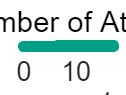

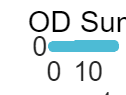

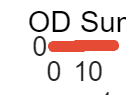

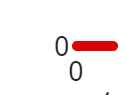

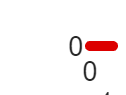

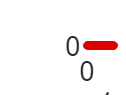

close all
clear all
colors=npg(100); %  basic colors
%main_dir='\\Artemis-pc\e\Data\2022-12-24\Abs-3551';
main_dir='E:\Data\2022-12-24\Abs-3551';
save_dir='D:\Documents\MATLAB\Figures for Yb-173\CatData';

load([main_dir,'\result.mat']);

clear relativeOD_fit coeff coeffoutput coefferr main_dir



## Reshape data

x_label='Ramsey interrogation time ms';

x_lim_low=0;
x_lim_high=0.250;

y_lim_low=-1.0;
y_lim_high=1.0;

precess_1_list=((0:7:245)+6)/1000; % ms
precess_1_list_plot=(-100:1:1100)/1000;
timestep=0.001;

precess_2_list=fliplr([0,1.1:1.1:4.4,8,12,20:20:180]);% s

length_0=length(relativeOD);
length_1=length(precess_1_list);
length_2=length(precess_2_list);

% reshape in row

% matrix_1 (N+ - N-)/(N+ + N-)
% matrix_2 (N+ + N-)
% matrix_3 (N+ + N-)/ N
% matrix_4  N+ / N
% matrix_5  N+ / N

matrix_1=reshape(relativeOD,length_1,length_0/length_1/length_2,length_2);
matrix_2=reshape(ODsum1+ODsum2,length_1,length_0/length_1/length_2,length_2);
matrix_3=reshape((ODsum1+ODsum2)./ODsum3,length_1,length_0/length_1/length_2,length_2);
matrix_4=reshape((ODsum1)./ODsum3,length_1,length_0/length_1/length_2,length_2);
matrix_5=reshape((ODsum2)./ODsum3,length_1,length_0/length_1/length_2,length_2);

% clear first data run
matrix_1(:,1,:)=[];
matrix_2(:,1,:)=[];
matrix_3(:,1,:)=[];
matrix_4(:,1,:)=[];
matrix_5(:,1,:)=[];

%
mean_1=mean(matrix_1,2); % mean in dim 2
std_1=std(matrix_1,0,2); % weight 0, dim 2
weight_1=1./std_1.^2;

mean_2=mean(mean(matrix_2,2),1);
std_2=mean(std(matrix_2,0,2),1);
weight_2=1./std_2.^2;

mean_3=mean(matrix_3,2);
std_3=std(matrix_3,0,2);
weight_3=1./std_3.^2;

mean_4=mean(matrix_4,2);
std_4=std(matrix_4,0,2);
weight_4=1./std_4.^2;

mean_5=mean(matrix_5,2);
std_5=std(matrix_5,0,2);
weight_5=1./std_5.^2;

%  use data in form of (:,:,i)


## Sindusal fitting two state

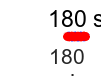

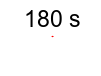

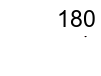

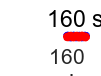

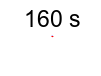

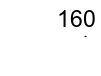

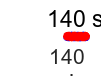

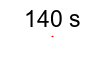

betaraw=[
    0.9656    0.9201    0.7757    0.8612   12.7680   12.7537   -2.1315   -2.1046
    0.9283    0.9217    0.9006    0.8669   12.8729   12.8966   -0.5443   -0.5553
    0.9300    0.9235    0.8930    0.8789   12.7654   12.9151    1.5590    1.3847
    0.9409    0.9301    0.9070    0.9362   12.8490   12.8464   -2.9104   -2.8950
    0.9595    0.9310    0.9243    0.9206   12.8390   12.8317   -0.9599   -0.9538
    0.9579    0.9456    0.9509    0.9352   12.8635   12.8125    1.0470    1.0740
    0.9748    0.9529    0.9523    0.9568   12.8087   12.8450    2.9733    2.9747
    0.9819    0.9586    0.9641    0.9571   12.8219   12.8666   -1.3032   -1.3314
    1.0164    0.9848    0.9700    0.9703   12.8093   12.7984    0.7635    0.7695
    1.0229    0.9857    0.9781    0.9761   12.8209   12.8383    2.8898    2.8661
    1.0226    0.9888    0.9822    0.9796   12.8288   12.8329    0.8376    0.8378
    1.0239    0.9740    0.9869    0.9704   12.8209   12.8318   -0.3350   -0.3381
    1.0469    1.0001    0.9887    0.9808   12.8181   12.8512   -1.0402   -1.0468
    1.0446    1.0080    0.9864    0.9818   12.8309   12.8371   -1.7332   -1.7380
    1.0488    1.0207    0.9911    0.9836   12.8368   12.8076   -2.4353   -2.4127
    1.0590    1.0120    0.9914    0.9849   12.8189   12.8581   -3.1082   -3.1342];

beta_list=zeros(size(mean_1,3),8);
beta_err_list=zeros(size(mean_1,3),8);

for i = 1:size(mean_1,3)
    %for i=1:1
    x_cell={precess_1_list,precess_1_list};
    y_cell={transpose(mean_4(:,:,i)),transpose(mean_5(:,:,i))};
    w_cell={transpose(weight_4(:,:,i)),transpose(weight_5(:,:,i))};
    % beta fitting parameters
    mdl1 = @(beta,x) beta(1)/2*(1+beta(3)*cos(2*pi*beta(5)*x+beta(7)));
    mdl2 = @(beta,x) beta(2)/2*(1-beta(4)*cos(2*pi*beta(6)*x+beta(8)));
    mdl_cell = {mdl1, mdl2};
    beta0=betaraw(i,:);
    [beta,r,J,Sigma,mse,errorparam,robustw] = nlinmultifit(x_cell, y_cell, mdl_cell, beta0,'weights',w_cell);
    % Calculate model predictions and confidence intervals
    [ypred1,delta1] = nlpredci(mdl1,precess_1_list_plot,beta,r,'covar',Sigma);
    [ypred2,delta2] = nlpredci(mdl2,precess_1_list_plot,beta,r,'covar',Sigma);
    beta_list(i,:)=beta;
    % Calculate parameter confidence intervals
    ci = nlparci(beta,r,'Jacobian',J);
    beta_err_list(i,:)=ci((length(ci)+1):(2*length(ci)))-ci(1:length(ci));

    fig_p2=figure;
    hold all;
    box on;

    plot(precess_1_list_plot+precess_2_list(i),ypred1,'Color','blue');
    plot(precess_1_list_plot+precess_2_list(i),ypred2,'Color','red');

    errorbar(precess_1_list+precess_2_list(i),mean_4(:,:,i),std_4(:,:,i),'o','Color','blue');
    errorbar(precess_1_list+precess_2_list(i),mean_5(:,:,i),std_5(:,:,i),'o','Color','red');

    title([num2str(precess_2_list(i)),' s']);
    ylim([0 1]);
    ylabel('P');
    xlabel('Precession time s');
    set(gca,'FontSize',16);
    xlim([x_lim_low+precess_2_list(i) x_lim_high+precess_2_list(i)]);
    ylim([0 y_lim_high]);
    saveas(fig_p2,[save_dir,'\Figure_p2_',num2str(i),'.png'])
    savefig(fig_p2,[save_dir,'\Figure_p2_',num2str(i),'.fig'])



    % need a loss factor
    diff_y1=diff(ypred1)./timestep;
    diff_y2=diff(ypred2)./timestep;

    fig_diff_y=figure;
    hold on
    plot(precess_1_list_plot(2:end)-timestep/2+precess_2_list(i),diff_y1.^2,'Color','blue');
    plot(precess_1_list_plot(2:end)-timestep/2+precess_2_list(i),diff_y2.^2,'Color','red');


    title([num2str(precess_2_list(i)),' s']);
    %ylim([-10 10]);
    ylabel('slope^2');
    xlabel('Precession time s');
    set(gca,'FontSize',16);
    xlim([x_lim_low+precess_2_list(i) x_lim_high+precess_2_list(i)]);


    fig_fisher_y=figure;
    hold on
    plot(precess_1_list_plot(2:end)-timestep/2+precess_2_list(i),diff_y1.^2./(ypred1(1:end-1)+ypred1(2:end))*2,'Color','blue');
    plot(precess_1_list_plot(2:end)-timestep/2+precess_2_list(i),diff_y2.^2./(ypred2(1:end-1)+ypred2(2:end))*2,'Color','red');
    plot(precess_1_list_plot(2:end)-timestep/2+precess_2_list(i),diff_y1.^2./(ypred1(1:end-1)+ypred1(2:end))*2+diff_y2.^2./(ypred2(1:end-1)+ypred2(2:end))*2,'Color','black');

    fisher(i)=max(diff_y1.^2./(ypred1(1:end-1)+ypred1(2:end))*2+diff_y2.^2./(ypred2(1:end-1)+ypred2(2:end))*2);
    title([num2str(precess_2_list(i)),' s']);
    %ylim([-10 10]);
    ylabel('fisher');
    xlabel('Precession time s');
    set(gca,'FontSize',16);
    xlim([x_lim_low+precess_2_list(i) x_lim_high+precess_2_list(i)]);

end

p_1=beta_list(:,1);
p_2=beta_list(:,2);
contrast_1=beta_list(:,3);
contrast_2=beta_list(:,4);
freq_1=beta_list(:,5);
freq_2=beta_list(:,6);
phase_1=beta_list(:,7);
phase_2=beta_list(:,8);

p_1_err=beta_err_list(:,1);
p_2_err=beta_err_list(:,2);
contrast_1_err=beta_err_list(:,3);
contrast_2_err=beta_err_list(:,4);
freq_1_err=beta_err_list(:,5);
freq_2_err=beta_err_list(:,6);
phase_1_err=beta_err_list(:,7);
phase_2_err=beta_err_list(:,8);

## Plot population decay - two parts

f_population_decay_2=figure;
hold all
h1=errorbar(precess_2_list',p_1,p_1_err,'o','Color','blue');
h2=errorbar(precess_2_list',p_2,p_2_err,'o','Color','red');

eqn='a*exp(-x^1/b^1)+c';
startpoints=[0.5 1 1];
lower=[0 0 0];
upper=[1.1 2000000 1];


fi_pop_coherent=fit(precess_2_list',p_1,eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',1./p_1_err.^2);
fi_pop_coherent_p1=fi_pop_coherent

fi_pop_coherent_p1 =      常规模型:
     fi_pop_coherent_p1(x) = a*exp(-x^1/b^1)+c
     系数(置信边界为 95%):
       a =      0.1109  (0.09386, 0.1279)
       b =       45.85  (24.89, 66.81)
       c =      0.9391  (0.9213, 0.9569)

plot((0:1:200),fi_pop_coherent(0:1:200),'LineWidth',1,'Color','blue');

fi_pop_coherent=fit(precess_2_list',p_2,eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',1./p_2_err.^2);
fi_pop_coherent_p2=fi_pop_coherent

fi_pop_coherent_p2 =      常规模型:
     fi_pop_coherent_p2(x) = a*exp(-x^1/b^1)+c
     系数(置信边界为 95%):
       a =     0.08645  (0.06288, 0.11)
       b =       56.48  (15.57, 97.39)
       c =      0.9196  (0.8942, 0.9451)

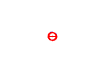

plot((0:1:200),fi_pop_coherent(0:1:200),'LineWidth',1,'Color','red');

ylabel('Population');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
ylim([0.8 1.1])
set(gca,'YScale','linear')

f_population_diff_decay_2=figure;

h1=errorbar(precess_2_list',p_1-p_2,sqrt(p_1_err.^2+p_2_err.^2),'o','Color','blue');

ylabel('Population difference');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
ylim([-0.1 0.1])
set(gca,'YScale','linear')

saveas(f_population_decay_2,[save_dir,'\Figure_p_decay.png'])

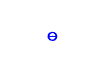

savefig(f_population_decay_2,[save_dir,'\Figure_p_decay.fig'])

saveas(f_population_diff_decay_2,[save_dir,'\Figure_p_diff.png'])

savefig(f_population_diff_decay_2,[save_dir,'\Figure_p_diff.fig'])


## Plot contrast decay - two parts

f_contrast_decay_2=figure;
hold all
h1=errorbar(precess_2_list',contrast_1,contrast_1_err,'o','Color','blue');
h2=errorbar(precess_2_list',contrast_2,contrast_2_err,'o','Color','red');

eqn='a*exp(-x^1/b^1)';
startpoints=[0.5 1];
lower=[0 0];
upper=[1.1 2000000];


fi_pop_coherent=fit(precess_2_list',contrast_1,eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',1./contrast_1_err.^2);
fi_pop_coherent_p1=fi_pop_coherent

fi_pop_coherent_p1 =      常规模型:
     fi_pop_coherent_p1(x) = a*exp(-x^1/b^1)
     系数(置信边界为 95%):
       a =      0.9899  (0.9849, 0.9948)
       b =        1367  (1080, 1654)

plot((0:1:200),fi_pop_coherent(0:1:200),'LineWidth',1,'Color','blue');

fi_pop_coherent=fit(precess_2_list',contrast_2,eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',1./contrast_2_err.^2);
fi_pop_coherent_p2=fi_pop_coherent

fi_pop_coherent_p2 =      常规模型:
     fi_pop_coherent_p2(x) = a*exp(-x^1/b^1)
     系数(置信边界为 95%):
       a =      0.9831  (0.98, 0.9862)
       b =        1525  (1281, 1770)

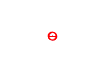

plot((0:1:200),fi_pop_coherent(0:1:200),'LineWidth',1,'Color','red');

ylabel('Contrast');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
ylim([0 1.1])
set(gca,'YScale','linear')

f_contrast_diff_decay_2=figure;

h1=errorbar(precess_2_list',contrast_1-contrast_2,sqrt(contrast_1_err.^2+contrast_2_err.^2),'o','Color','blue');

ylabel('Contrast difference');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
ylim([-0.1 0.1])
set(gca,'YScale','linear')


saveas(f_contrast_decay_2,[save_dir,'\Figure_c_decay.png'])

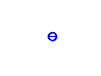

savefig(f_contrast_decay_2,[save_dir,'\Figure_c_decay.fig'])

saveas(f_contrast_diff_decay_2,[save_dir,'\Figure_c_diff.png'])

savefig(f_contrast_diff_decay_2,[save_dir,'\Figure_c_diff.fig'])

%% 

## Plot frequency - two parts

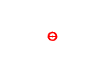

f_freq_2=figure;
hold all
h1=errorbar(precess_2_list',freq_1,freq_1_err,'o','Color','blue');
h2=errorbar(precess_2_list',freq_2,freq_2_err,'o','Color','red');

% eqn='a*exp(-x^1/b^1)';
% startpoints=[0.5 1];
% lower=[0 0];
% upper=[1.1 2000000];
% 
% 
% fi_pop_coherent=fit(precess_2_list',contrast_1,eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',1./contrast_1_err.^2);
% fi_pop_coherent_p1=fi_pop_coherent
% plot((0:1:200),fi_pop_coherent(0:1:200),'LineWidth',1,'Color','blue');
% 
% fi_pop_coherent=fit(precess_2_list',contrast_2,eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',1./contrast_2_err.^2);
% fi_pop_coherent_p2=fi_pop_coherent
% plot((0:1:200),fi_pop_coherent(0:1:200),'LineWidth',1,'Color','red');
% 
ylabel('Frequency (Hz)');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
ylim([12.5 13])
set(gca,'YScale','linear')

f_freq_diff_2=figure;

h1=errorbar(precess_2_list',freq_1-freq_2,sqrt(freq_1_err.^2+freq_2_err.^2),'o','Color','blue');

ylabel('Frequency difference (Hz)');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
ylim([-0.25 0.25])
set(gca,'YScale','linear')


saveas(f_freq_2,[save_dir,'\Figure_freq.png'])

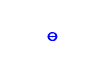

savefig(f_freq_2,[save_dir,'\Figure_freq.fig'])

saveas(f_freq_diff_2,[save_dir,'\Figure_freq_diff.png'])

savefig(f_freq_diff_2,[save_dir,'\Figure_freq_diff.fig'])



sum(freq_1./freq_1_err.^2+freq_2./freq_2_err.^2)./sum(1./freq_1_err.^2+1./freq_2_err.^2)

ans = 12.8321



xxxx=1:32;
freq_list=[freq_1',freq_2'];
freq_weight=[1./freq_1_err'.^2,1./freq_2_err'.^2];

## Plot phase - two parts

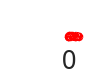

f_phase_2=figure;
hold all
h1=errorbar(precess_2_list',phase_1,phase_1_err,'o','Color','blue');
h2=errorbar(precess_2_list',phase_2,phase_2_err,'o','Color','red');

% eqn='a*exp(-x^1/b^1)';
% startpoints=[0.5 1];
% lower=[0 0];
% upper=[1.1 2000000];
% 
% 
% fi_pop_coherent=fit(precess_2_list',contrast_1,eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',1./contrast_1_err.^2);
% fi_pop_coherent_p1=fi_pop_coherent
% plot((0:1:200),fi_pop_coherent(0:1:200),'LineWidth',1,'Color','blue');
% 
% fi_pop_coherent=fit(precess_2_list',contrast_2,eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',1./contrast_2_err.^2);
% fi_pop_coherent_p2=fi_pop_coherent
% plot((0:1:200),fi_pop_coherent(0:1:200),'LineWidth',1,'Color','red');
% 
ylabel('Phase offset (rad)');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
ylim([-pi pi])
set(gca,'YScale','linear')

f_phase_diff_2=figure;

h1=errorbar(precess_2_list',phase_1-phase_2,sqrt(phase_1_err.^2+phase_2_err.^2),'o','Color','blue');

ylabel('Phase difference (rad)');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
ylim([-0.25 0.25])
set(gca,'YScale','linear')


saveas(f_phase_2,[save_dir,'\Figure_phase.png'])

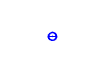

savefig(f_phase_2,[save_dir,'\Figure_phase.fig'])

saveas(f_phase_diff_2,[save_dir,'\Figure_phase_diff.png'])

savefig(f_phase_diff_2,[save_dir,'\Figure_phase_diff.fig'])

## Plot population decay - average

eqn='a*exp(-x^1/b^1)+c';
startpoints=[0.5 1 1];
lower=[0 0 0];
upper=[1.1 2000000 1];

f_p_decay=figure

f_p_decay =   Figure (71) - 属性:

      Number: 71
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


fi_p_cat=fit(precess_2_list',(p_1+p_2)./2,eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',1./(p_1_err.^2+p_2_err.^2));
plot((0:1:200),fi_p_cat(0:1:200)./(fi_p_cat.a+fi_p_cat.c),'LineWidth',2,'Color',colors(5,:));
fi_p_cat

fi_p_cat =      常规模型:
     fi_p_cat(x) = a*exp(-x^1/b^1)+c
     系数(置信边界为 95%):
       a =     0.09968  (0.0824, 0.117)
       b =       51.47  (26.5, 76.44)
       c =      0.9281  (0.9096, 0.9465)

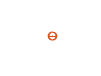

p_average=(p_1+p_2)./2./(fi_p_cat.a+fi_p_cat.c);
p_average_err=sqrt(p_1_err.^2+p_2_err.^2)/2./(fi_p_cat.a+fi_p_cat.c);

hold all

h1=errorbar(precess_2_list',p_average,p_average_err,'o');
ylabel('Population');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
ylim([0 1])
set(gca,'YScale','linear')

saveas(f_p_decay,[save_dir,'\p_decay.png'])

savefig(f_p_decay,[save_dir,'\p_decay.fig'])

## Plot contrast decay - average

eqn='a*exp(-x^1/b^1)';
startpoints=[1 1000];
lower=[0 0];
upper=[1.1 2000000];

f_c_decay=figure

f_c_decay =   Figure (105) - 属性:

      Number: 105
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性



c_average=(contrast_1+contrast_2)./2;
c_average_err=sqrt(contrast_1_err.^2+contrast_2_err.^2)./2;

fi_c_cat=fit(precess_2_list',c_average,eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',1./c_average_err.^2);
plot((0:1:200),fi_c_cat(0:1:200),'LineWidth',2,'Color',colors(5,:));
fi_c_cat

fi_c_cat =      常规模型:
     fi_c_cat(x) = a*exp(-x^1/b^1)
     系数(置信边界为 95%):
       a =      0.9864  (0.9833, 0.9895)
       b =        1447  (1242, 1652)

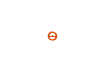


hold all

h1=errorbar(precess_2_list',c_average,c_average_err,'o');
ylabel('Contrast');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
ylim([0 1])
set(gca,'YScale','linear')

saveas(f_c_decay,[save_dir,'\c_decay.png'])

savefig(f_c_decay,[save_dir,'\c_decay.fig'])

## Plot  sensitivity

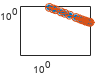

g_I=0.27196;
nuclear_magneton=2*pi*7.6225932291*10^6;%Hz/T
gyro_factor=g_I*nuclear_magneton;

precess_2_list_sensitivity=precess_2_list+mean(precess_1_list);

% sensitivity=1./precess_2_list_sensitivity./slope_max*12.5*100./((mean_3_mean).^0.5)';
% sensitivity_error=(amp_error./amp_list)'.*sensitivity./((mean_3_mean).^0.5)';



% Classical Fisher
sensitivity1=1./precess_2_list_sensitivity'./c_average./((p_average).^0.5)/gyro_factor*10^9/5;
% Quantum Fisher information correction
sigmaz=spinOp(5/2,'z');

for k = 1:length(c_average)
    rho = reconstruction(c_average(k),p_average(k));
    QFIlist(k) = fisher_information(rho,sigmaz);
end

sensitivity2=1./precess_2_list_sensitivity'./sqrt(QFIlist')/gyro_factor*10^9;

sensitivity_error=((c_average_err./c_average)+0.5*(p_average_err./p_average)).*sensitivity;

sensitivity_decay=figure;
errorbar(precess_2_list_sensitivity,sensitivity1,sensitivity_error,'.','MarkerSize',14)
hold on
errorbar(precess_2_list_sensitivity,sensitivity2,sensitivity_error,'o')
set(gca,'XScale','log')
set(gca,'YScale','log')
xlim([0.1 200])
ylim([1e-5 10])
box on

hold on

savefig(sensitivity_decay,[save_dir,'\SensitivityDecay.fig'])
saveas(sensitivity_decay,[save_dir,'\SensitivityDecay.png'])

## Plot  sensitivity - fisher

g_I=0.27196; %0.67989(3)/(5/2)=0.27196(2)
nuclear_magneton=2*pi*7.6225932291*10^6;%Hz/T
gyro_factor=g_I*nuclear_magneton;

precess_2_list_sensitivity=precess_2_list+mean(precess_1_list);

% sensitivity=1./precess_2_list_sensitivity./slope_max*12.5*100./((mean_3_mean).^0.5)';
% sensitivity_error=(amp_error./amp_list)'.*sensitivity./((mean_3_mean).^0.5)';

sensitivity=1./precess_2_list_sensitivity'./c_average./((p_average).^0.5)/gyro_factor*10^9/5;
sensitivity_error=((c_average_err./c_average)+0.5*(p_average_err./p_average)).*sensitivity;

sensitivity_decay=figure;
%scatter(precess_2_list_sensitivity,sensitivity)
%hold on
%errorbar(precess_2_list_sensitivity,sensitivity,sensitivity_error,'o')
set(gca,'XScale','log')
set(gca,'YScale','log')
xlim([0.1 200])
%ylim([1e-5 10])
box on
errorbar(precess_2_list_sensitivity,sensitivity,sensitivity_error,'o')
hold on

%scatter(precess_2_list_sensitivity,1./precess_2_list_sensitivity./sqrt(fisher)/(gyro_factor)*10^9)
set(gca,'XScale','log')
set(gca,'YScale','log')
xlim([1 300])
ylim([6e-2 1.05e2])

box on
HL=plot(0.001:0.1:500,1./(0.001:0.1:500)/(5)/(gyro_factor/10^9))

HL =   Line - 属性:

              Color: [0.8500 0.3250 0.0980]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1.0000e-03 0.1010 0.2010 0.3010 0.4010 0.5010 0.6010 0.7010 0.8010 0.9010 1.0010 1.1010 1.2010 1.3010 1.4010 1.5010 1.6010 1.7010 1.8010 1.9010 2.0010 2.1010 2.2010 2.3010 2.4010 2.5010 2.6010 2.7010 2.8010 2.9010 3.0010 3.1010 … ]
              YData: [1.5355e+04 152.0271 76.3917 51.0124 38.2911 30.6482 25.5486 21.9040 19.1695 17.0419 15.3394 13.9462 12.7850 11.8023 10.9598 10.2297 9.5907 9.0269 8.5257 8.0772 7.6735 7.3083 6.9763 6.6731 6.3951 6.1394 5.9034 5.6848 5.4819 … ]

  显示 所有属性


SQL=plot(0.001:0.1:500,1./(0.001:0.1:500)/(sqrt(5))/(gyro_factor/10^9))

SQL =   Line - 属性:

              Color: [0.9290 0.6940 0.1250]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1.0000e-03 0.1010 0.2010 0.3010 0.4010 0.5010 0.6010 0.7010 0.8010 0.9010 1.0010 1.1010 1.2010 1.3010 1.4010 1.5010 1.6010 1.7010 1.8010 1.9010 2.0010 2.1010 2.2010 2.3010 2.4010 2.5010 2.6010 2.7010 2.8010 2.9010 3.0010 3.1010 … ]
              YData: [3.4334e+04 339.9429 170.8171 114.0672 85.6215 68.5314 57.1285 48.9789 42.8642 38.1068 34.2999 31.1846 28.5880 26.3906 24.5069 22.8742 21.4455 20.1847 19.0640 18.0611 17.1585 16.3419 15.5994 14.9214 14.3000 13.7282 13.2004 … ]

  显示 所有属性


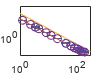


fisher_t=fisher;
fisher_phi=fisher_t./(gyro_factor*1.2417e+03/10^9).^2;
fihser_B=fisher_phi.*(gyro_factor.*precess_2_list_sensitivity).^2;

scatter(precess_2_list_sensitivity,1./sqrt(fihser_B)*10^9.*(fi_p_cat.a+fi_p_cat.c))


%savefig(sensitivity_decay,[save_dir,'\SensitivityDecay.fig'])


12.8321/5/gyro_factor*2*pi*10^6

ans = 1.2380

0.0037/5/gyro_factor*2*pi*10^6

ans = 3.5696e-04

## Vacuum decay

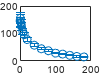

% number decay

n_list=squeeze(mean_2(:,:,:));
n_std=squeeze(std_2(:,:,:));
[n_max,n_max_index]=max(n_list);
n_fit_weight=1./n_std.^2;

n_norm=n_list./n_max;
n_std_norm=n_std./n_max;

figure;
errorbar(precess_2_list(1:end)',n_list,n_std,'o')


eqn='exp(-x/a)*b';
startpoints=[50 1];
lower=[20 0];
upper=[100 1];

fi=fit(precess_2_list(1:end)',n_norm(1:end),eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',n_fit_weight(1:end));
f_vacuum_decay=figure;
plot((1:1:200),fi(1:1:200),'LineWidth',1.5,'Color',colors(5,:));
hold on

chi_fit=sum(((fi(precess_2_list)-n_norm(1:end))./n_std_norm).^2)

chi_fit = 34.2427


chi_fit_reduced=chi_fit/(length(precess_2_list)-2)

chi_fit_reduced = 2.4459


fi.a

ans = 78.5356

temp = confint(fi);
(temp(2,:)-temp(1,:))/4

ans =     5.2091    0.0481


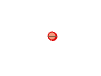


h3=errorbar(precess_2_list',n_norm,n_std_norm,'o');


ylabel('Atom number');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
h3.Color=colors(9,:);
h4.MarkerSize=6;
h3.MarkerEdgeColor=colors(8,:);
h3.MarkerFaceColor=colors(5,:);
set(gca,'YScale','log')
ylim([0.01 1])
saveas(f_vacuum_decay,[save_dir,'\Vacuum decay.png'])

## Magnetic field

sum(freq_1./freq_1_err.^2)/sum(1./freq_1_err.^2)./gyro_factor*2*pi/5

ans = 1.2374e-06

## Save result

save([save_dir,'\cat.mat'])


function rho = reconstruction(c,p)
rho=1/4*(1-p)*eye(6);
rho(1,1)=p/2;
rho(6,6)=p/2;
rho(1,6)=1i*p*c/2;
rho(6,1)=-1i*p*c/2;
end